function [y, savings] = calculate(alpha, n, m, r)
    N = 1;

    y = 1:m;
    y(1) = N;
    for i = 2:n
        y(i) = y(i-1) * (1+r(i));
    end
    for i = (n+1):m
        y(i) = y(n) * (1-alpha);
    end

    savings = 1:m;
    savings(1) = 0;

    for i = 2:n
        savings(i) = savings(i-1) * (1+r(i)) + y(i)*alpha;
    end
    for i = (n+1):m
        savings(i) = savings(i-1) * (1+r(i)) - y(i);
    end
end

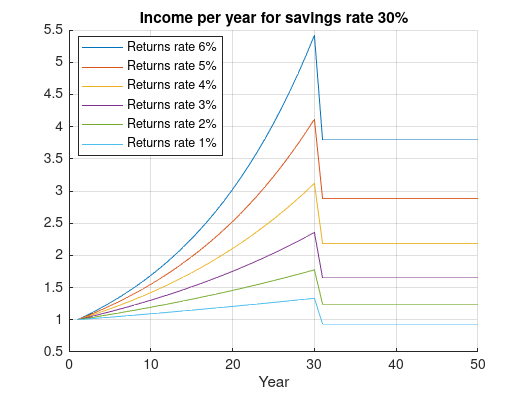

hold on;
grid on;

rates = 0.06:-0.01:0.01;
alpha = 0.3;
n = 30;
m = n + 20;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([1 m]));
    
    title("Income per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(y, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

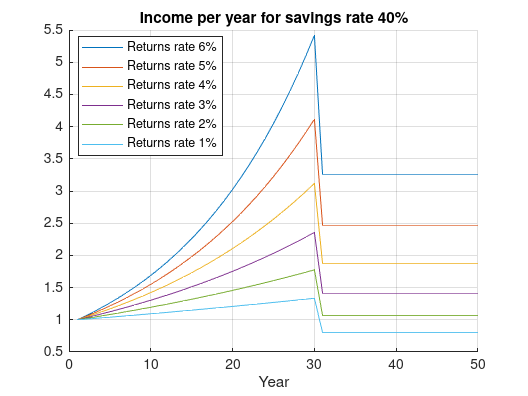

figure;
hold on;
grid on;

rates = 0.06:-0.01:0.01;
alpha = 0.4;
n = 30;
m = n + 20;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([1 m]));
    
    title("Income per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(y, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

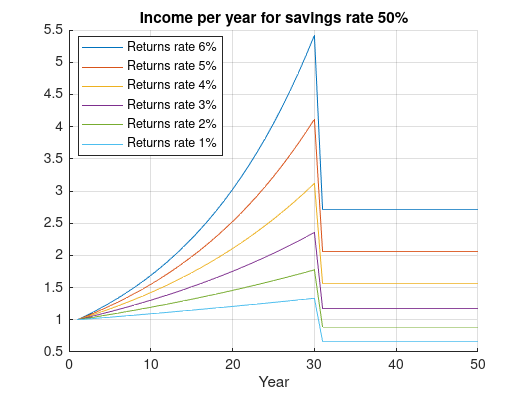

figure;
hold on;
grid on;

rates = 0.06:-0.01:0.01;
alpha = 0.5;
n = 30;
m = n + 20;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([1 m]));
    
    title("Income per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(y, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

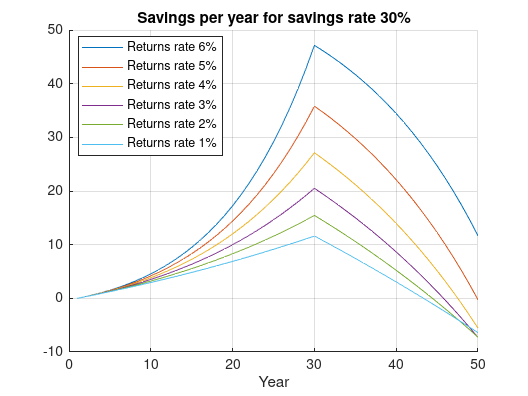

figure;
hold on;
grid on;

alpha = 0.3;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([m 1]));
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

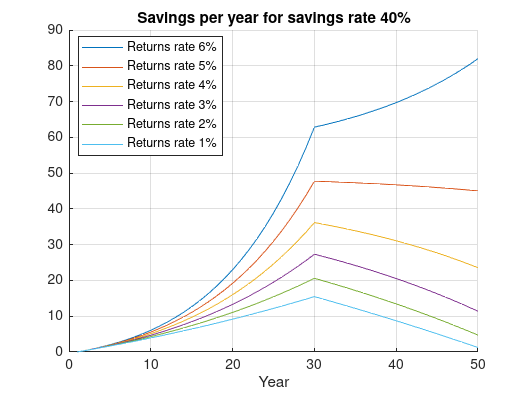

figure;
hold on;
grid on;

alpha = 0.4;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([m 1]));
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

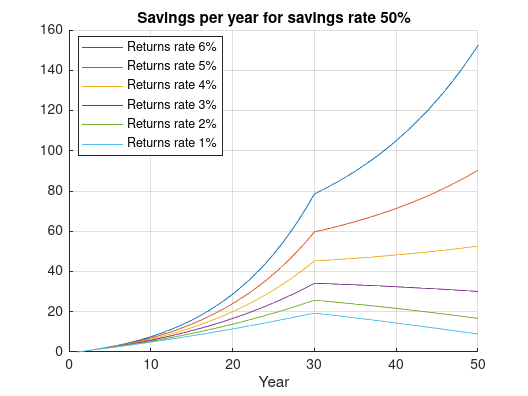

figure;
hold on;
grid on;

alpha = 0.5;

for r = rates
    [y, savings] = calculate(alpha, n, m, r * ones([m 1]));
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(r*100) + '%');
end


legend('show');

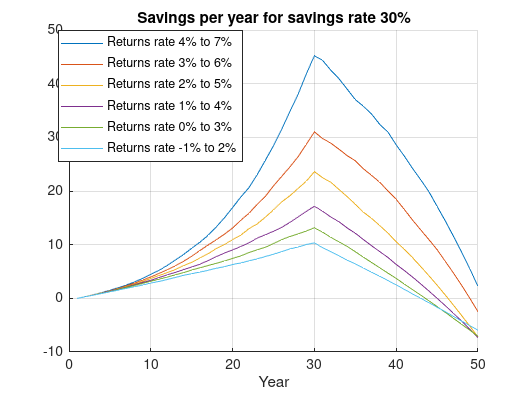

figure;
hold on;
grid on;

alpha = 0.3;

rng('default');  % For reproducibility

for r = rates
    minRate = r-0.02;
    maxRate = r+0.01;
    pd = makedist('Uniform','Lower',minRate,'Upper',maxRate);
    actualRates = random(pd, 1, m);
    
    [y, savings] = calculate(alpha, n, m, actualRates);
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(minRate*100) + '% to '+ string(maxRate*100) + '%');
end


legend('show');

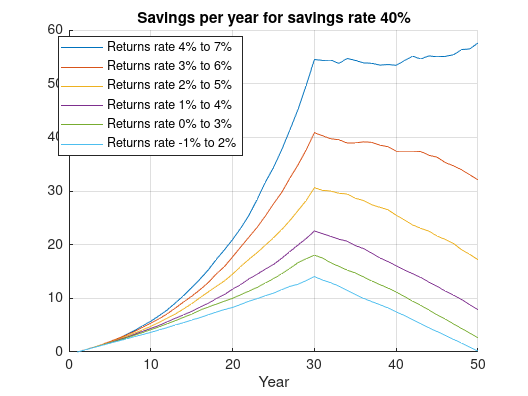

figure;
hold on;
grid on;

alpha = 0.4;

for r = rates
    minRate = r-0.02;
    maxRate = r+0.01;
    pd = makedist('Uniform','Lower',minRate,'Upper',maxRate);
    actualRates = random(pd, 1, m);
    
    [y, savings] = calculate(alpha, n, m, actualRates);
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(minRate*100) + '% to '+ string(maxRate*100) + '%');
end


legend('show');

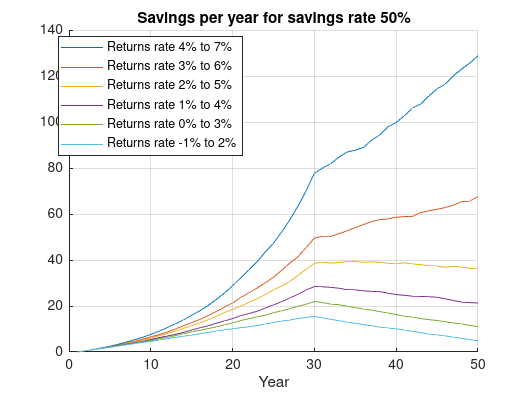

figure;
hold on;
grid on;

alpha = 0.5;

for r = rates
    minRate = r-0.02;
    maxRate = r+0.01;
    pd = makedist('Uniform','Lower',minRate,'Upper',maxRate);
    actualRates = random(pd, 1, m);
    
    [y, savings] = calculate(alpha, n, m, actualRates);
    
    title("Savings per year for savings rate " + string(alpha*100) + "%");
    xlabel("Year");
    legend("Position", [0.1477 0.6070 0.2744, 0.3018]);
    plot(savings, 'DisplayName', 'Returns rate ' + string(minRate*100) + '% to '+ string(maxRate*100) + '%');
end


legend('show');